## Vehicular Platoons Coordination Simulator

This is the main file that one needs to execute to generate the results that we show in our paper.

clear all
close all
clc

rng(7)

Creation of the network of platoons

%% Setup
network_index = 0;                  % network Index
numOfPlatoons = 3;                  % num of platoons
numOfVehicles = [4,5,6];            % num of vehicles in each platoon
totalNumOfVehicles = sum(numOfVehicles);

%% Initial setup
vehicleSeperationMean = 5;
vehicleSeperationVar = 2; 
platoonSeperationMean = 10;
platoonSeperationVar = 2;

%% Define the initial vehicular position/velocity/acceleration 
vehiclePosition = 0;                % Zeroth vehicle position
vehicleVelocity = 0;                % Zeroth vehicle velocity
vehicleAcceleration = 0;            % Zeroth vehicle acceleration
vehiclePositionDesired = 0;         % Desired zeroth vehicle position
vehicleVelocityDesired = 2;         % Desired zeroth vehicle velocity
vehicleAccelerationDesired = 0;     % Desired zeroth vehicle acceleration

state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
des_state_ki = [vehiclePositionDesired; vehicleVelocityDesired; vehicleAccelerationDesired];

%% Define the initial states and desired states for all the vehicles
for k = 1:1:numOfPlatoons           % for every platoon k
    
    parameters_k = [];
    noiseMean_k = [];
    noiseStd_k = [];
    states_k =  [];                       % initial states collection
    des_states_k =  [];                   % desired signals to be tracked collection
        
    for i = 1:1:numOfVehicles(k)    % for every vehicle in the k-th platoon

        % Vehicle parameters (assumed homogenuous)
        mass_ki = 1500;
        length_ki = 2.5;
        Af_ki = 2.2;
        rho_ki = 0.78;
        Cd_ki = 0.35;
        Cr_ki = 0.067;
        tau_ki = 0.25;

        % Collection of the initial/initially desired states of each vehicle
        states_k = [states_k, state_ki];
        des_states_k =  [des_states_k, des_state_ki];
        
        % Define the vehicle position/velocity/acceleration 
        vehiclePosition = vehiclePosition - vehicleSeperationMean -...
            vehicleSeperationVar*(rand(1)-0.5);
        vehicleVelocity = 0;
        vehicleAcceleration = 0;
        state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
                
        % Desired vehicular position/velocity/acceleration profile
        vehiclePositionDesired = vehiclePositionDesired - vehicleSeperationMean;
        vehicleVelocityDesired = 2;
        vehicleAccelerationDesired = 0;
        des_state_ki = [vehiclePositionDesired; vehicleVelocityDesired; vehicleAccelerationDesired];

        % Collection of vehicle parameters
        vehicleParameters_i = [mass_ki; length_ki; Af_ki; rho_ki; Cd_ki; Cr_ki; tau_ki];
        parameters_k = [parameters_k, vehicleParameters_i];

        % Noise parameters
        noisemean_ki = rand(3,1);
        noisestd_ki = 0.1*rand(3,1);

        noiseMean_k = [noiseMean_k, noisemean_ki];
        noiseStd_k = [noiseStd_k, noisestd_ki];
            
    end
    
    vehiclePosition = states_k(1,end) - platoonSeperationMean - platoonSeperationVar*(rand(1)-0.5);
    vehiclePositionDesired = des_states_k(1,end) - platoonSeperationMean;
    
    state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
    des_state_ki = [vehiclePositionDesired; vehicleVelocityDesired; vehicleAccelerationDesired];

    parameters{k} = parameters_k;
    states{k} = states_k;
    des_states{k} = des_states_k;
    noiseMean{k} = noiseMean_k;
    noiseStd{k} = noiseStd_k;
      
end

net = Network(network_index,numOfPlatoons,numOfVehicles,parameters,states,des_states,noiseMean,noiseStd);

Plotting the network of platoons

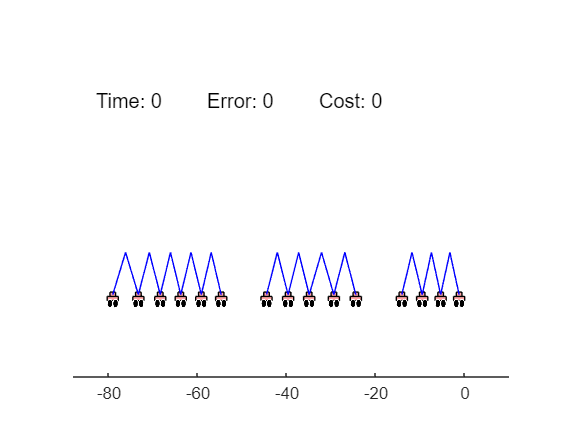

% Platoon simulation video figure setup
figure(1)
hold on 
ax1 = gca;                   % gca = get current axis handle
ax1.YAxis.Visible = 'off';   % hide out the y-axis from the plot
% axis off
% set(gcf,'Visible','off')
net.drawNetwork(1)

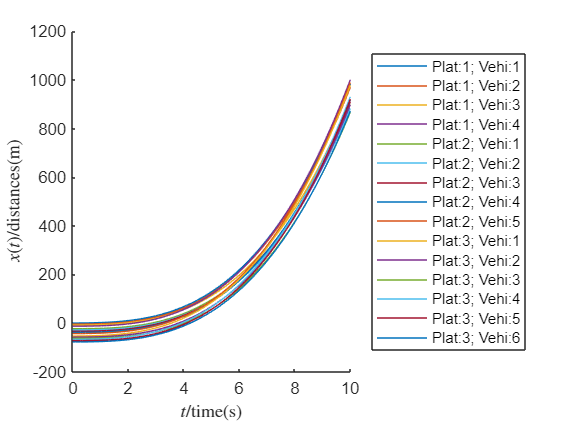


% Update the states and plot them in real time as an animation
dt = 0.01;
tMax = 10;
tArray = 0:dt:tMax;

for t = tArray

    % Use this update function to achieve the update of the entire program
    net.update(dt)
%     net.redrawNetwork(1)
%     pause(0.01)
    
end

% Plot the state histories
figure(2)
hold on
for k = 1:1:numOfPlatoons
    for i = 1:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(1,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$x(t)$/distances(m)','Interpreter','latex')
legend(Location="eastoutside")

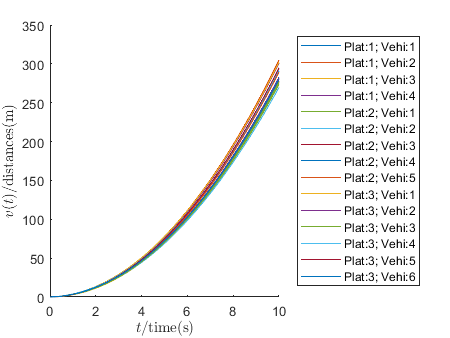


figure(3)
hold on
for k = 1:1:numOfPlatoons
    for i = 1:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(2,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$v(t)$/distances(m)','Interpreter','latex')
legend(Location="eastoutside")